# **Identification of Linear System from Sampled Data - Lab 2 **

## **Rohan Dhansoia & Lynn Daher**

## Load data for identification

clear all
clc
load("dataidentlab2.mat");
Tprbs = Ts*(0:length(uprbs)-1)

Tprbs =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


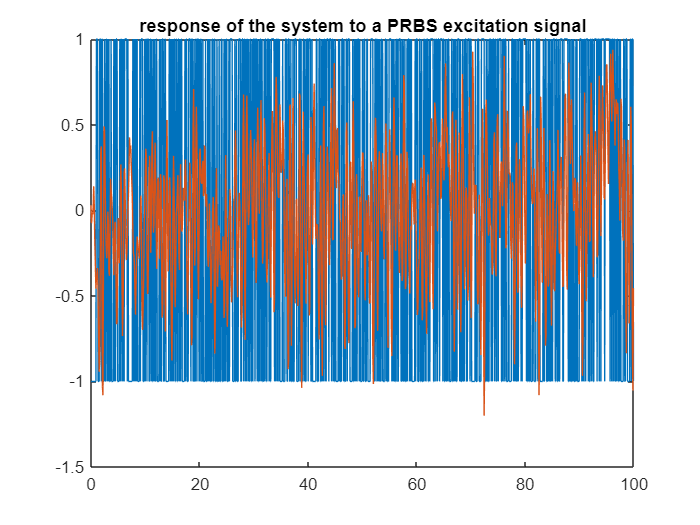

plot(Tprbs,uprbs,Tprbs,yprbs);title('response of the system to a PRBS excitation signal');

T211 = Ts*(0:length(u211)-1)

T211 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


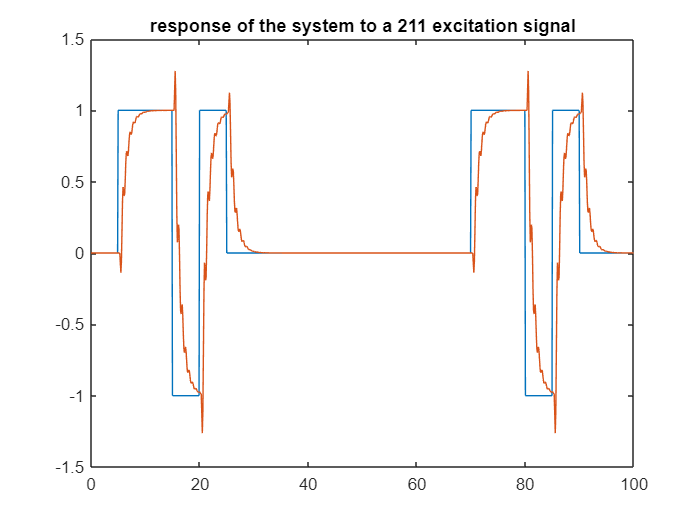

plot(T211,u211,T211,y211);title('response of the system to a 211 excitation signal');

Tstep = Ts*(0:length(ustep)-1)

Tstep =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


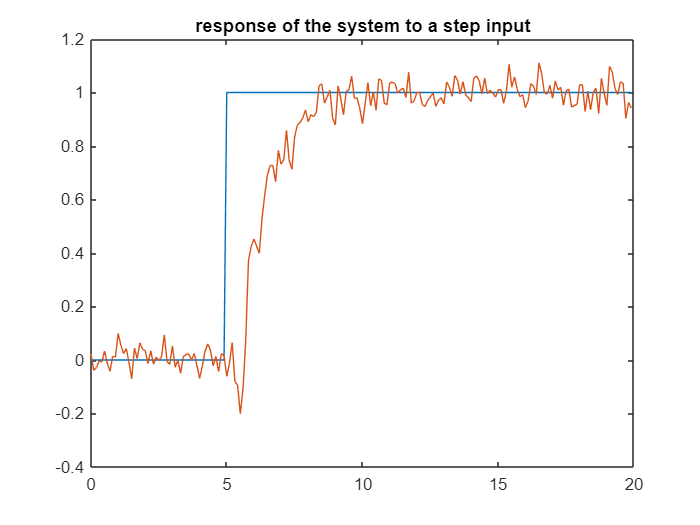

plot(Tstep,ustep,Tstep,ystep);title('response of the system to a step input');

## Part 1: Data Preparation – PRBS Excitation Signal

uident = uprbs(1:500);
yident = yprbs(1:500);
uvalid = uprbs(500:end);
yvalid = yprbs(500:end);

## 1) Evaluate delay - RLS & ELS 

To evaluate if we have a pure delay for our system, the number of poles (na) is set to zero, the number of zeros (nb) is set to a very high value of 100 to observe the system respose, and nk is set to 0. As observed in the graph below and the values of B, we have the first 4 values of B = 0. Hence the delay is set to 3. 

The value of nk for RLS and ELS will be the same. (nk = 3) 

na = 0;
nb = 100;
nk = 0;
[A,B] = RLS(uident,yident,na,nb,nk);
B

B =          0    0.0012   -0.0011    0.0029   -0.0678   -0.0675    0.0748    0.2100    0.2122    0.1037   -0.0138   -0.0507    0.0124    0.0938    0.1217    0.0762    0.0117   -0.0250   -0.0109    0.0372    0.0680    0.0539    0.0171   -0.0090   -0.0087    0.0084    0.0360    0.0314    0.0154   -0.0051   -0.0081    0.0027    0.0145    0.0198    0.0125   -0.0005   -0.0031   -0.0018    0.0048    0.0065    0.0080    0.0016   -0.0013   -0.0043    0.0018    0.0045    0.0035   -0.0010   -0.0016   -0.0024


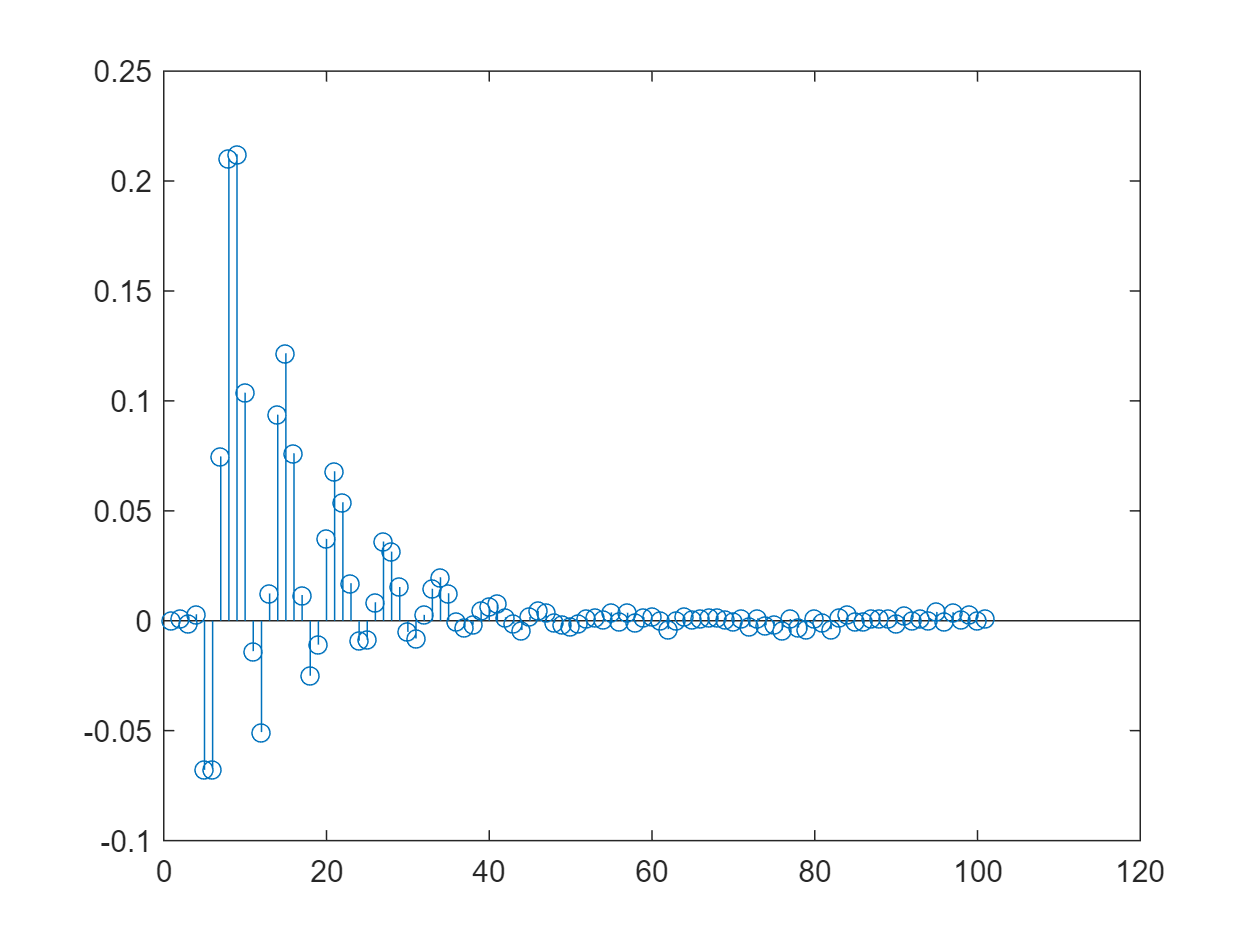

stem(B)

## 2) Identification of a Discrete Time Model (RLS)

### **2.1) Using combinations of na and nb values**

A loop was run with na and nb values varying from 0 to 10 and the J and AIC were plotted

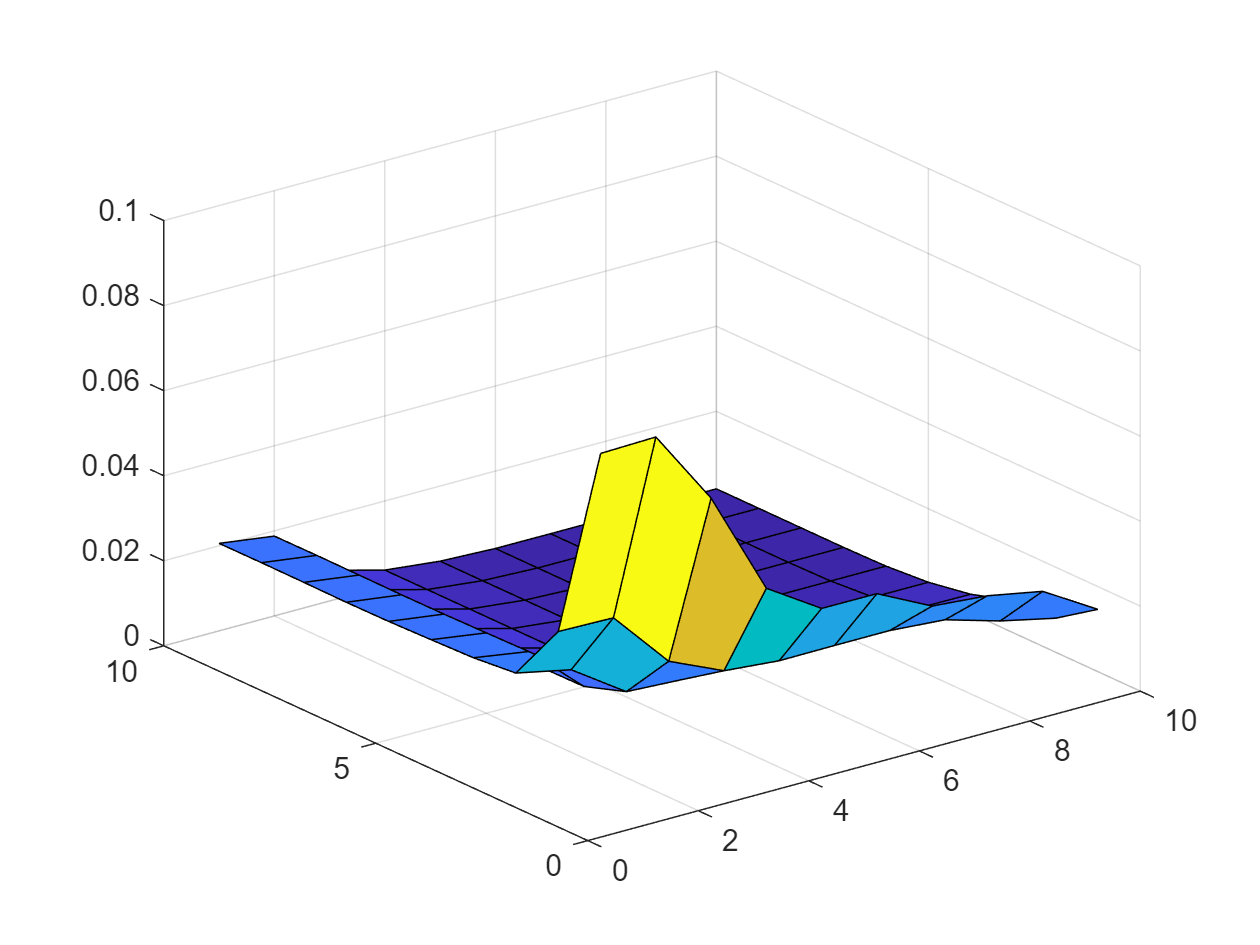

Ja = ones(10,10);
AICa = ones(10,10);

for nx=1:10
    for ny=1:10
        
        na = nx;
        nb = ny;
        nk = 3;
        [A,B] = RLS(uident,yident,na,nb,nk);
        [err, J, AIC] = computerrors(uvalid,yvalid,A,B,[]);
        Ja(nx,ny) = J;
        AICa(nx,ny) = AIC;

    end
end
surf(Ja)

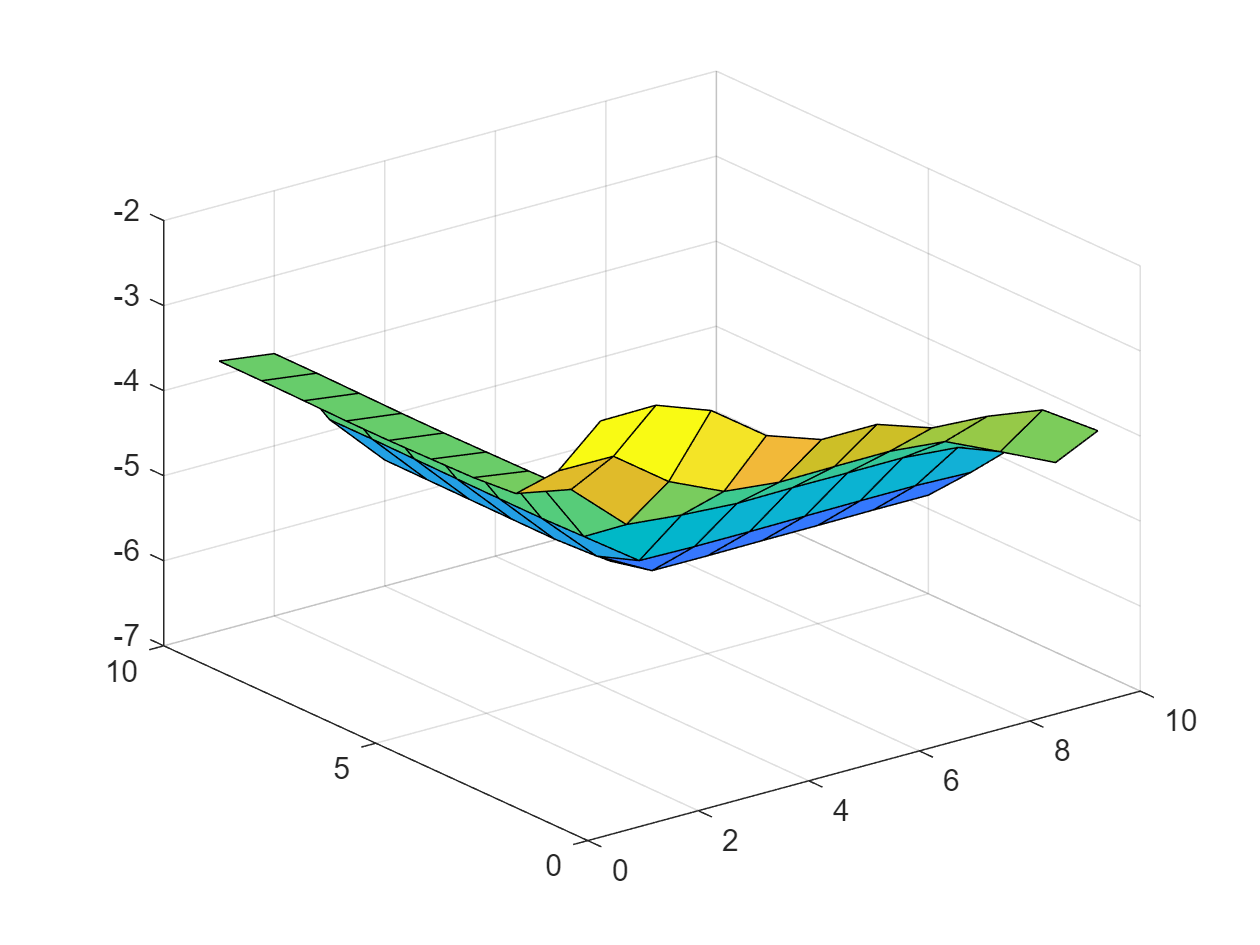

surf(AICa)

From the graph, values of na and nb between 4 and 7 fall within a region which has low J and AIC. Further increase in na and nb only led to minor improvements in the J and AIC values.

### 2.2) Validation was performed to identify good values

A higher value of na and nb would lead to a better model, however, would lead to a high order model which would be difficult to control and work on. Thus, through validation a balance was struck between precision and order of model.

Different values of na and nb were run in the range of 4 to 7 (as identified before), and the steady state error was looked at as an identifying criteria. In case of the system response, the steady state response for a step looks like the steady state value is approx. 1. Thus, dcgain can be checked and results within 1% error can be deemed acceptable 

for nx=4:7
    for ny=4:7  
        [A,B] = RLS(uident,yident,nx,ny,3);
        sysid = tf(B,A,Ts,'variable','z^-1');
        if dcgain(sysid)>0.99
            nx,ny
        end
    end
end

nx = 6

ny = 5

Thus, the identified system is to have 6 poles, 5 zeros, and a delay of 3

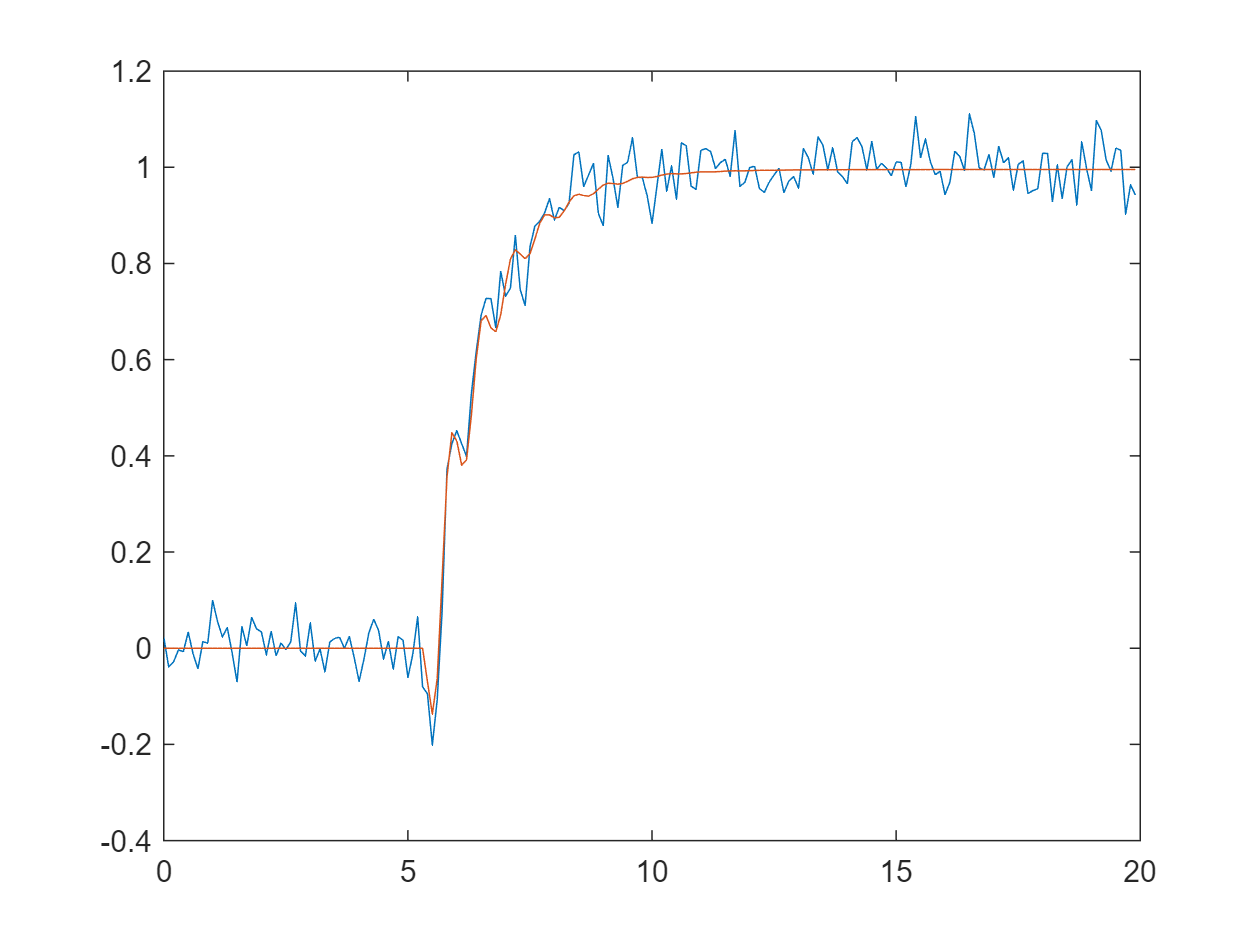

[A,B] = RLS(uident,yident,6,5,3);

sysid = tf(B,A,Ts,'variable','z^-1');
ysim = lsim(sysid,ustep,Tstep);
plot(Tstep,ystep,Tstep,ysim)

### 2.3) Analysis of Residuals 

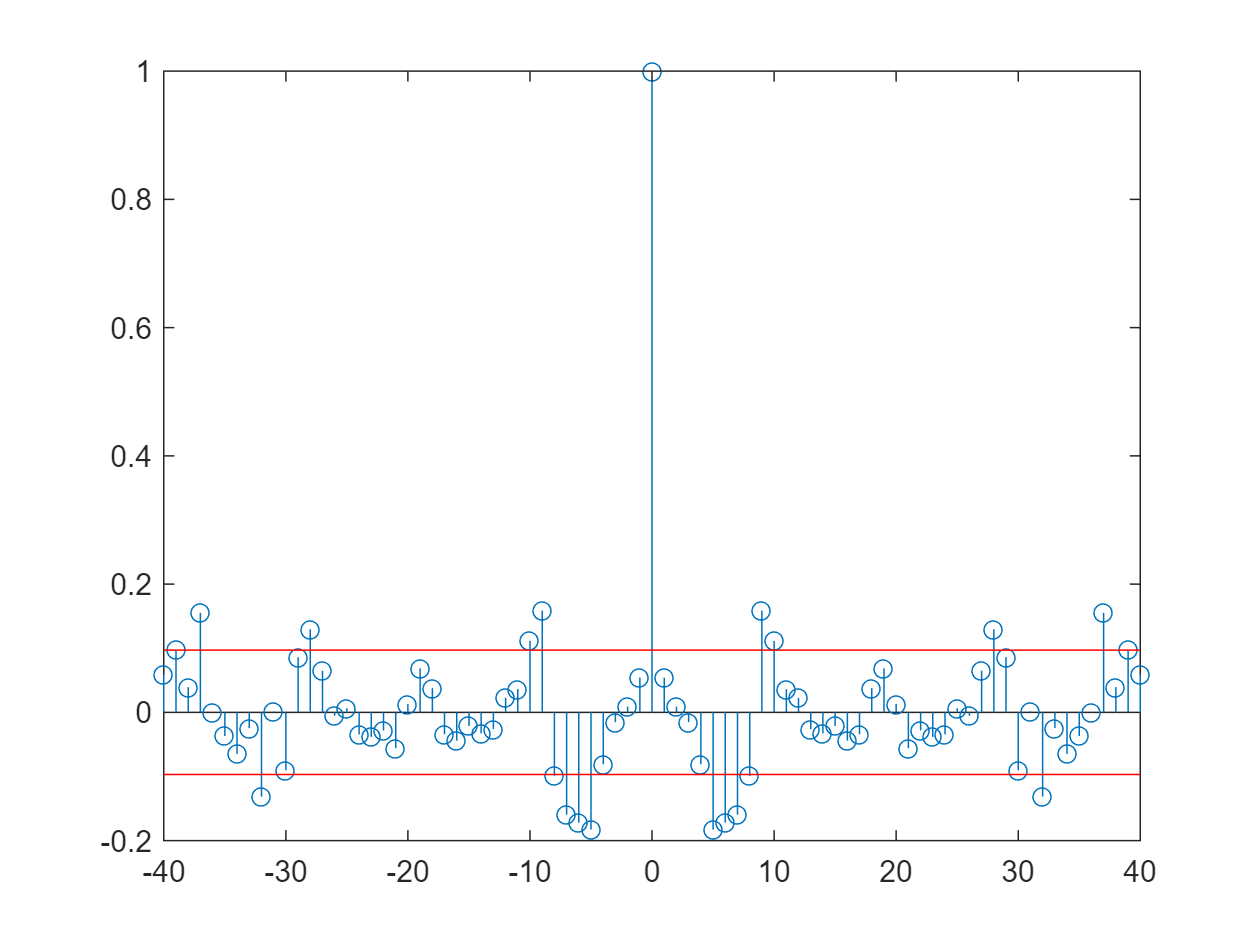

N = length(uvalid);
x = xcorr(err,err);
x = x/x(N);
stem(-40:1:40,x(N-40:N+40));
line([-40 40],[2.17/sqrt(N) 2.17/sqrt(N)],'color','r');
line([-40 40],[-2.17/sqrt(N) -2.17/sqrt(N)],'color','r');

From the residuals, it can be concluded that the noise in this case is not pure gaussian white noise, but close. This is what induces errors in the estimation.

## 3) Identification of a Discrete Time Model (ELS)

### **3.1) Using combinations of na, nb, &nc values**

A loop was run with na, nb, and nc values varying from 0 to 10. The minimum value of J was identified (0.0016), and the values of na, nb, & nc that falls within 15% of the minimum J as well as the 1% error of the dcgain were printed out. 

Jb = ones(10,10);
AICb = ones(10,10);
minJ = 1;
for nx=1:10
    for ny=1:10
        for nz=1:10
            na = nx;
            nb = ny;
            nc = nz;
            nk = 3;
            [A,B,C] = ELS(uident,yident,na,nb,nc,nk);
            [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C);
            Jb(nx,ny,nz) = J;
            AICb(nx,ny,nz) = AIC;

            if J < minJ
                minJ = J;
            end

        end 
    end
end
minJ

minJ = 0.0016

%minAIC
for nx=1:10
    for ny=1:10
        for nz=1:10
            if Jb(nx,ny,nz) < minJ*1.15 
           
                [A,B,C] = ELS(uident,yident,nx,ny,nz,3);
                sysid = tf(B,A,Ts,'variable','z^-1');
                if dcgain(sysid)>0.99
                    nx; ny; nz;%uncomment to see list of values
                end
            end

        end 
    end
end

### 2) Validation was performed to identify good values

To find the best na, nb, and nc values from the ones printed above (commented), and keeping in mind that a higher value of na & nb would lead to a better model but also, a higher order model is difficult to control. Thus, through validation a balance was struck between precision and order of model. (Values of na and nb were chosen to be not too high.)

By slight trail and error, the printed values that deemed to be acceptable are na = 4, nb = 4, and nc = 6. 

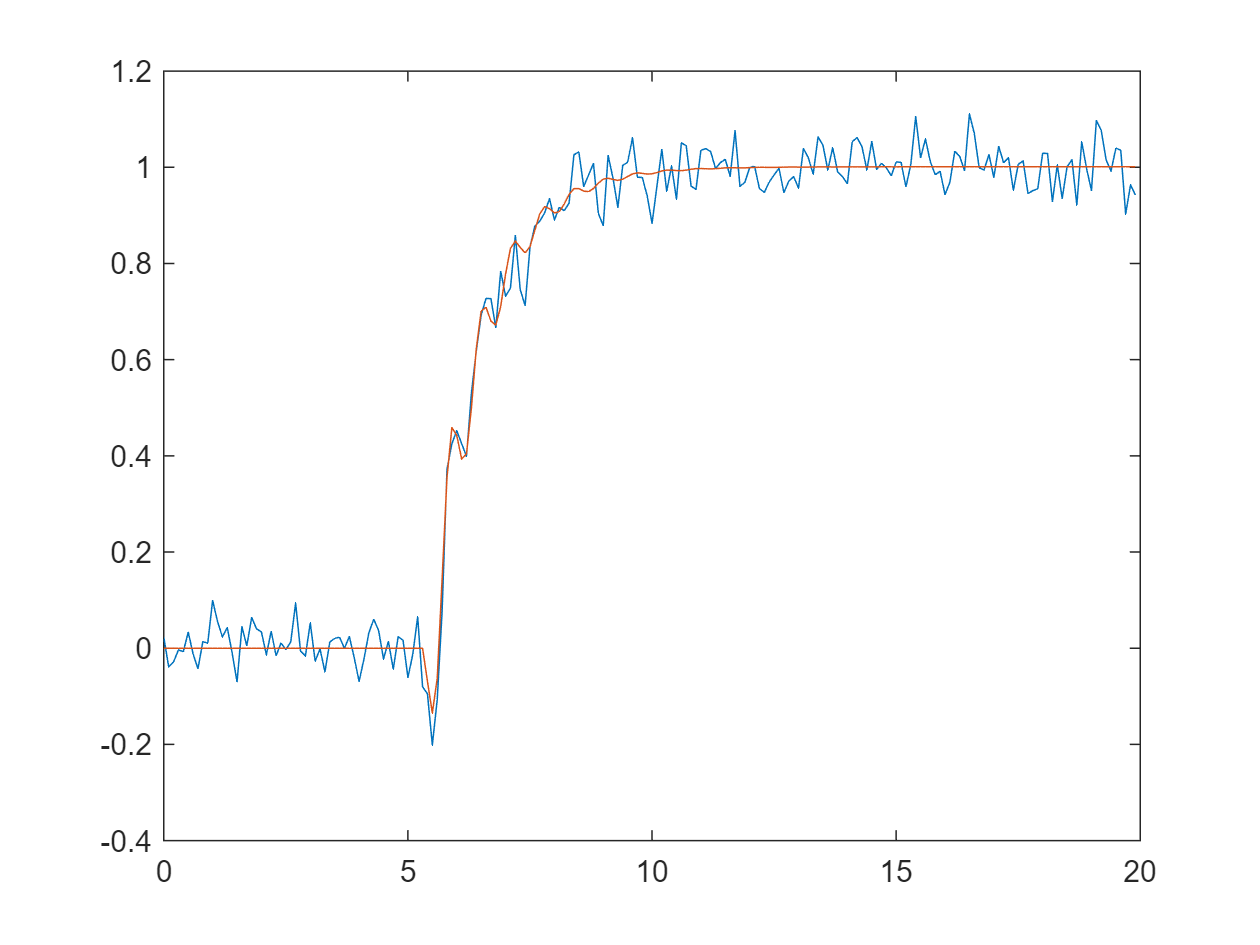

na = 4; %nb of poles
nb = 4; %nb of zeros 
nc = 6;
nk = 3; % fixed cnst value

[A,B,C] = ELS(uident,yident,na,nb,nc,nk);
sysid = tf(B,A,Ts,'variable','z^-1');
ysim = lsim(sysid,ustep,Tstep);
plot(Tstep,ystep,Tstep,ysim);

### **3) Analysis of Residules **

By analysing the residules, ELS gives a better fit then RLS. The values shown below are between the two red lines which is proof that the error vector is a white noise. 

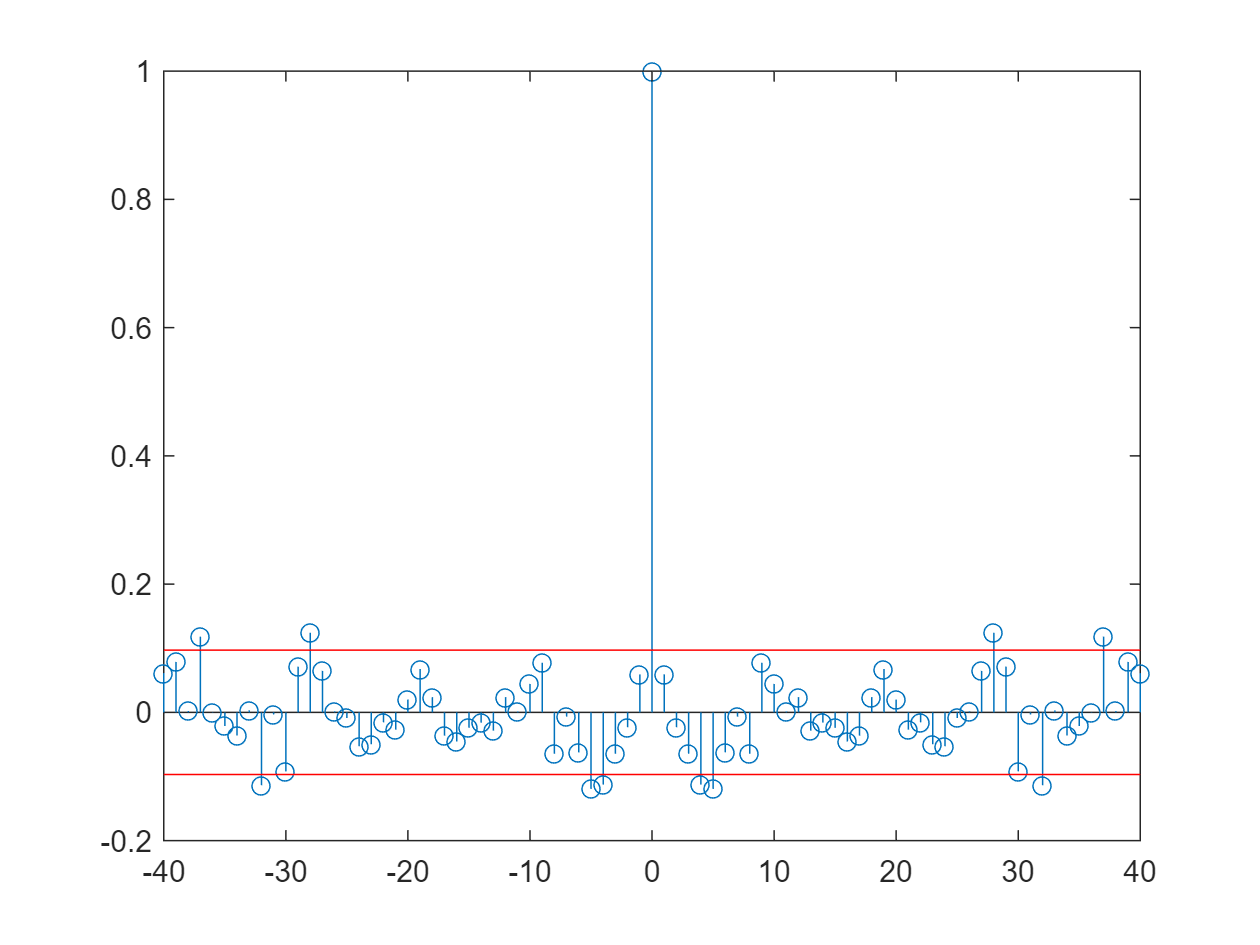

N = length(uvalid);
x = xcorr(err,err);
x = x/x(N);
stem(-40:1:40,x(N-40:N+40));
line([-40 40],[2.17/sqrt(N) 2.17/sqrt(N)],'color','r');
line([-40 40],[-2.17/sqrt(N) -2.17/sqrt(N)],'color','r');

## Part 2: Data Preparation – 211 Excitation Signal 

uident = u211(1:500);
yident = y211(1:500);
uvalid = u211(500:end);
yvalid = y211(500:end);

## 1) Evaluate delay - RLS & ELS 

To evaluate if we have a pure delay for our system, the number of poles (na) is set to zero, the number of zeros (nb) is set to a very high value of 100 to observe the system respose, and nk is set to 3. As observed in the graph below and the values of B, we have the first 4 values of B = 0. Hence the delay is set to 3. 

The value of nk for RLS and ELS will be the same. (nk = 3) 

na = 0;
nb = 100;
nk = 0;
[A,B] = RLS(uident,yident,na,nb,nk);
B

B =          0    0.0000   -0.0000   -0.0000   -0.0685   -0.0697    0.0735    0.2073    0.2146    0.1054   -0.0141   -0.0480    0.0114    0.0933    0.1213    0.0781    0.0093   -0.0261   -0.0074    0.0375    0.0643    0.0518    0.0158   -0.0111   -0.0097    0.0124    0.0318    0.0317    0.0147   -0.0028   -0.0070    0.0024    0.0146    0.0181    0.0112    0.0009   -0.0040   -0.0008    0.0060    0.0097    0.0075    0.0021   -0.0018   -0.0013    0.0021    0.0049    0.0047    0.0020   -0.0005   -0.0010


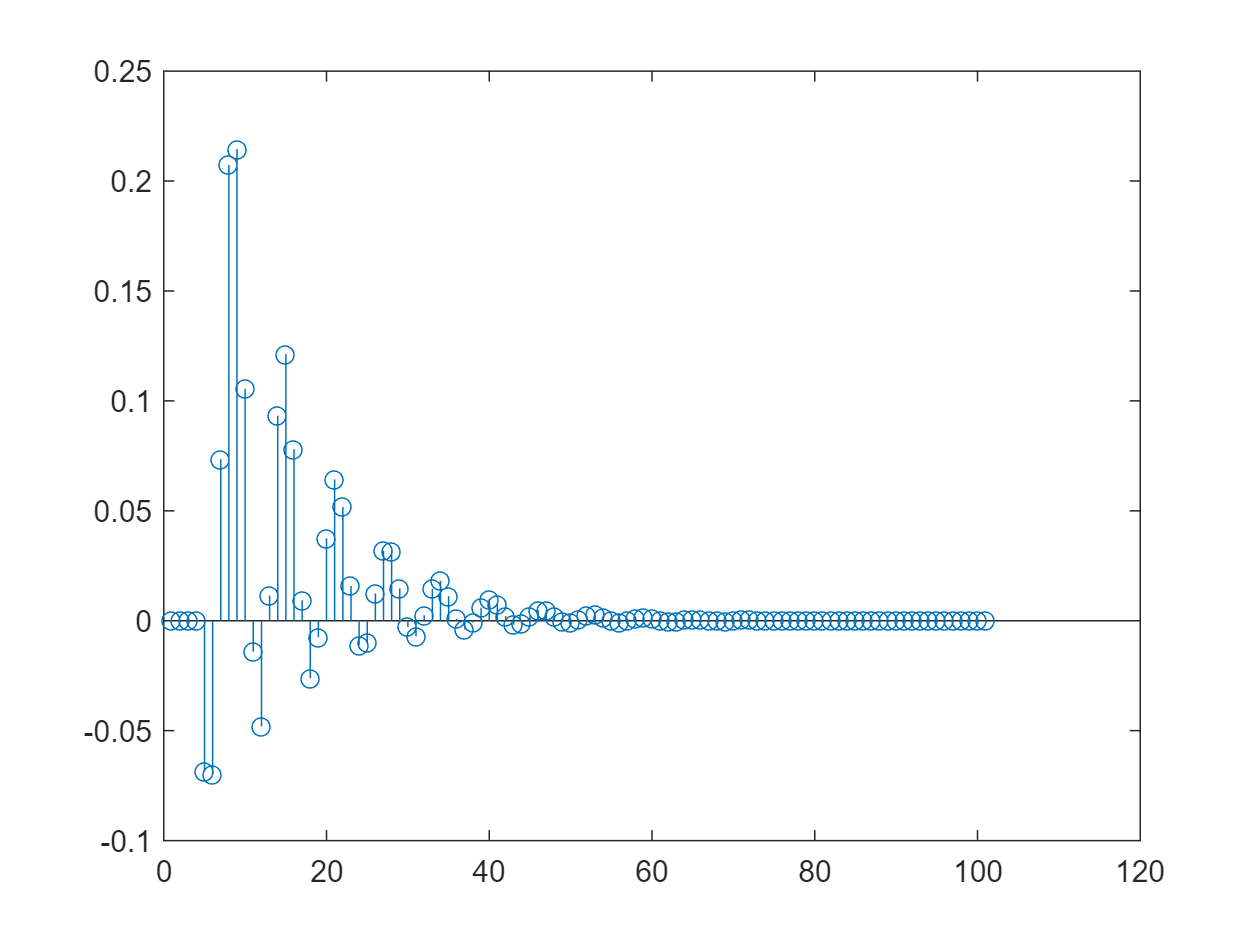

stem(B)

## 2) Identification of a Discrete Time Model (RLS)

### **2.1) Using combinations of na and nb values**

A loop was run with na and nb values varying from 0 to 10 and the J and AIC were plotted

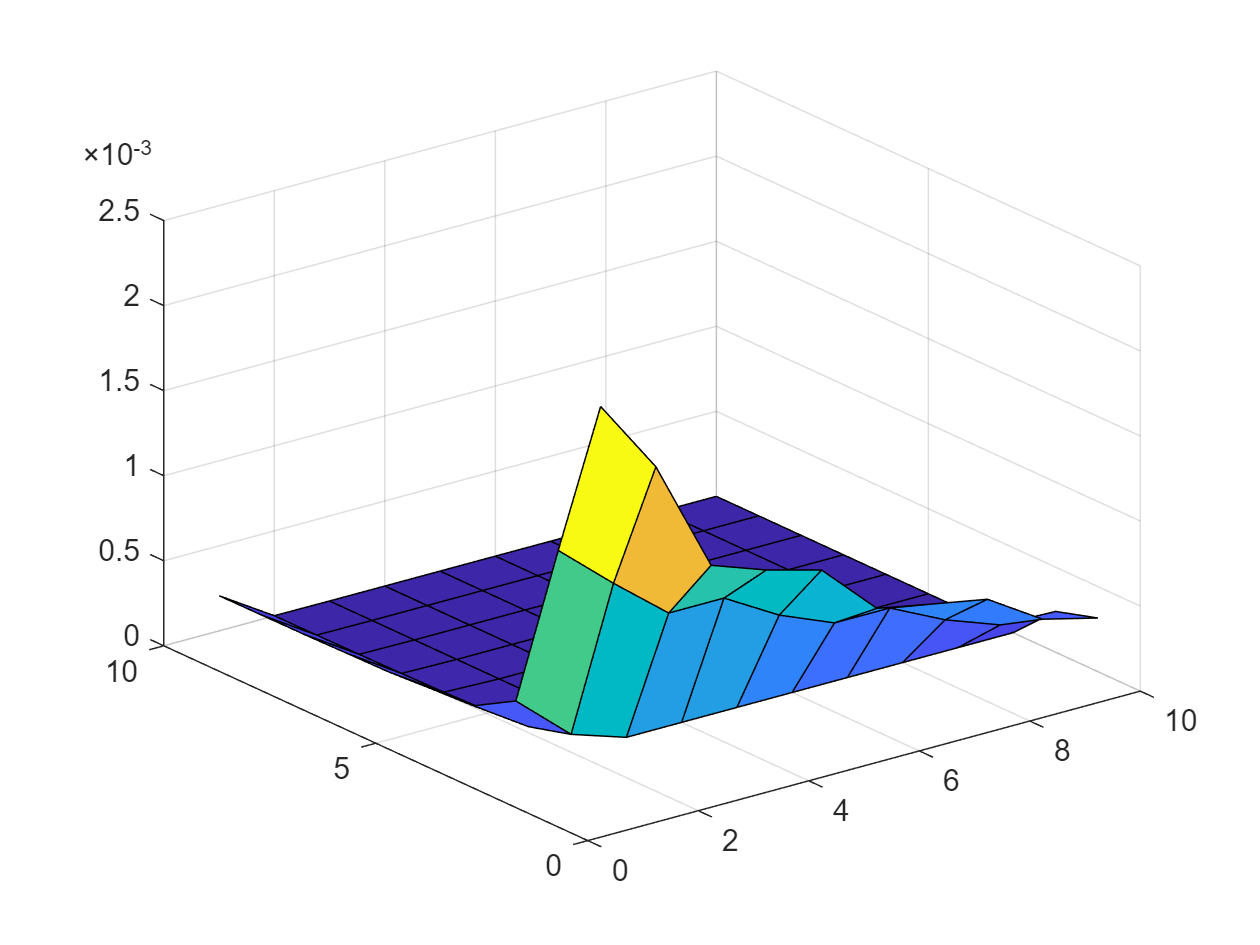

Ja = ones(10,10);
AICa = ones(10,10);
for nx=1:10
    for ny=1:10
        na = nx;
        nb = ny;
        nk = 3;
        [A,B] = RLS(uident,yident,na,nb,nk);
        [err, J, AIC] = computerrors(uvalid,yvalid,A,B,[]);
        Ja(nx,ny) = J;
        AICa(nx,ny) = AIC;
    end
end
surf(Ja)

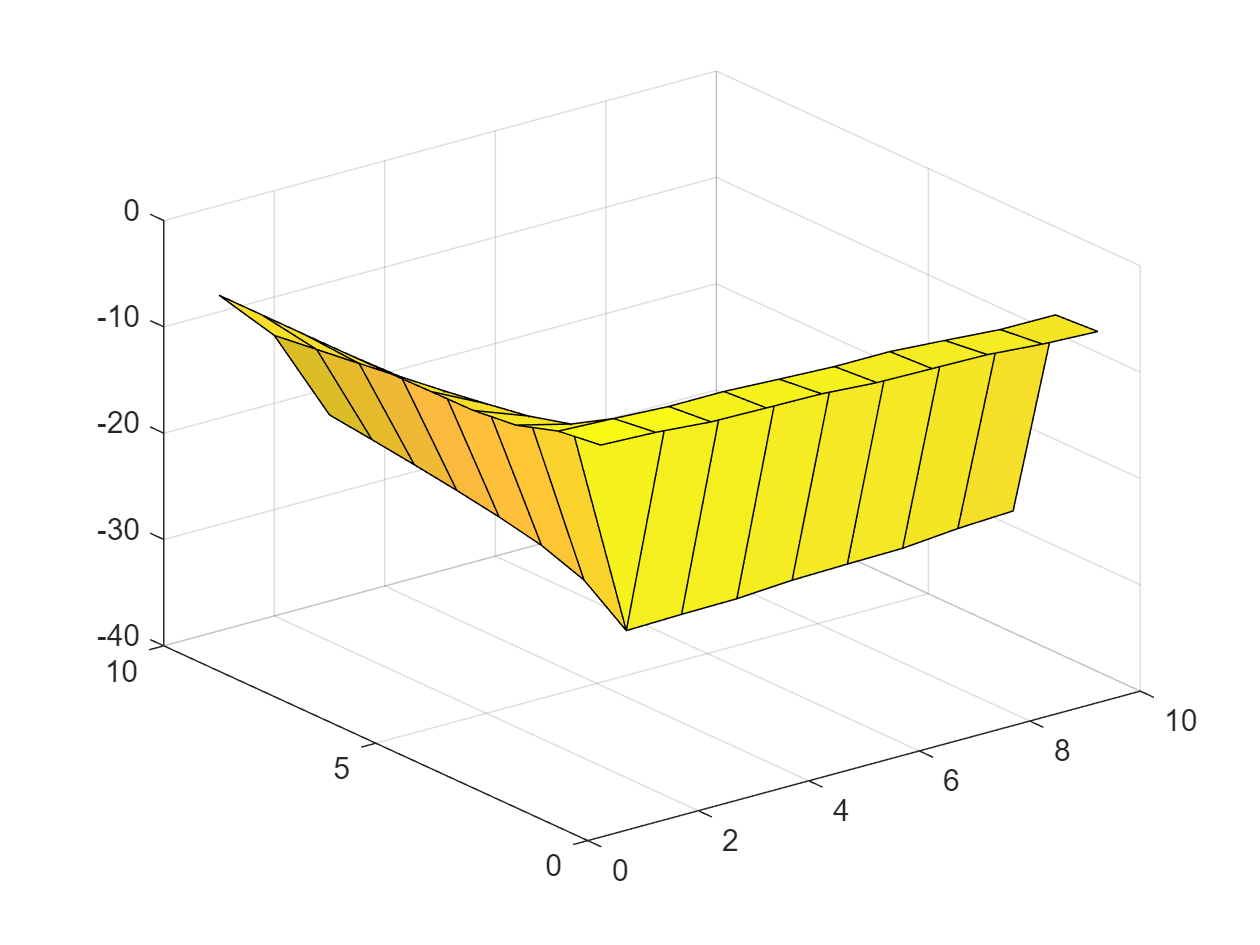

surf(AICa);

From the plots, it can be seen that a value of na between 3 and 8 and nb between 4 and 8 lead to low values of J and AIC. Further increase in na and nb only led to minor improvements in the J and AIC values.

### 2.2) Validation was performed to identify good values

As stated in the previous case, a higher value of na and nb would lead to a better model, however it would lead to a high order model which would be difficult to control and work on. Thus, through validation a balance was struck between precision and order of model.

Different values of na and nb were run in the range of 3 to 7 and 4 to 7 respectively (as identified before), and the steady state error was looked at as an identifying criteria. In case of the system response, the steady state response for a step looks like the steady state value is approx. 1. Thus, dcgain can be checked and results within 1% error can be deemed acceptable 

for nx=3:8
    for ny=4:8  
        [A,B] = RLS(uident,yident,nx,ny,0);
        sysid = tf(B,A,Ts,'variable','z^-1');
        if dcgain(sysid)>0.99    
            nx; ny; %uncomment to see list
        end
    end
end

The minimum value of nx and ny was 3 and 4. Thus, it was used to set the poles and zeros.

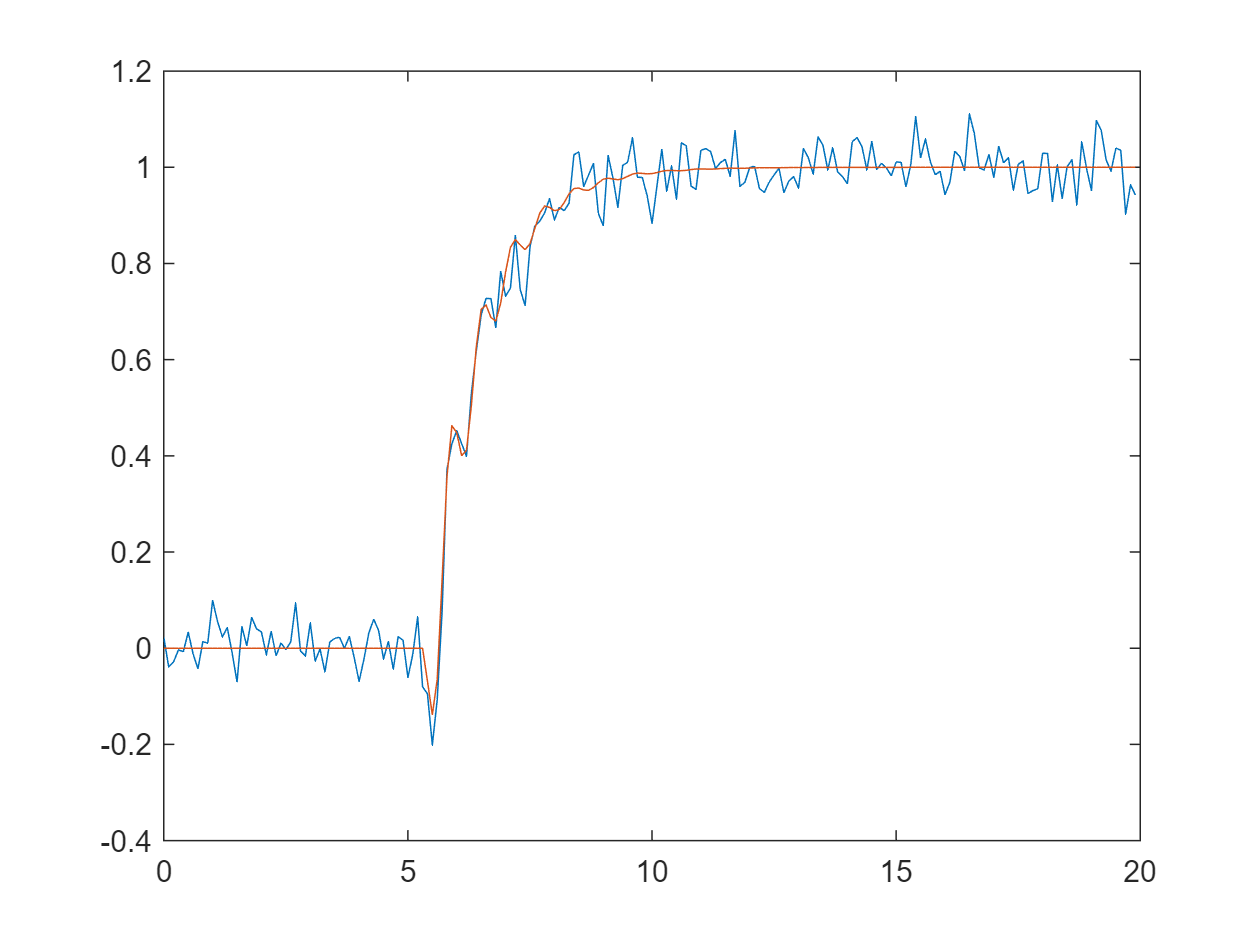

[A,B] = RLS(uident,yident,3,4,3);
sysid = tf(B,A,Ts,'variable','z^-1');
ysim = lsim(sysid,ustep,Tstep);
plot(Tstep,ystep,Tstep,ysim)

### 2.3) Analysis of Residuals 

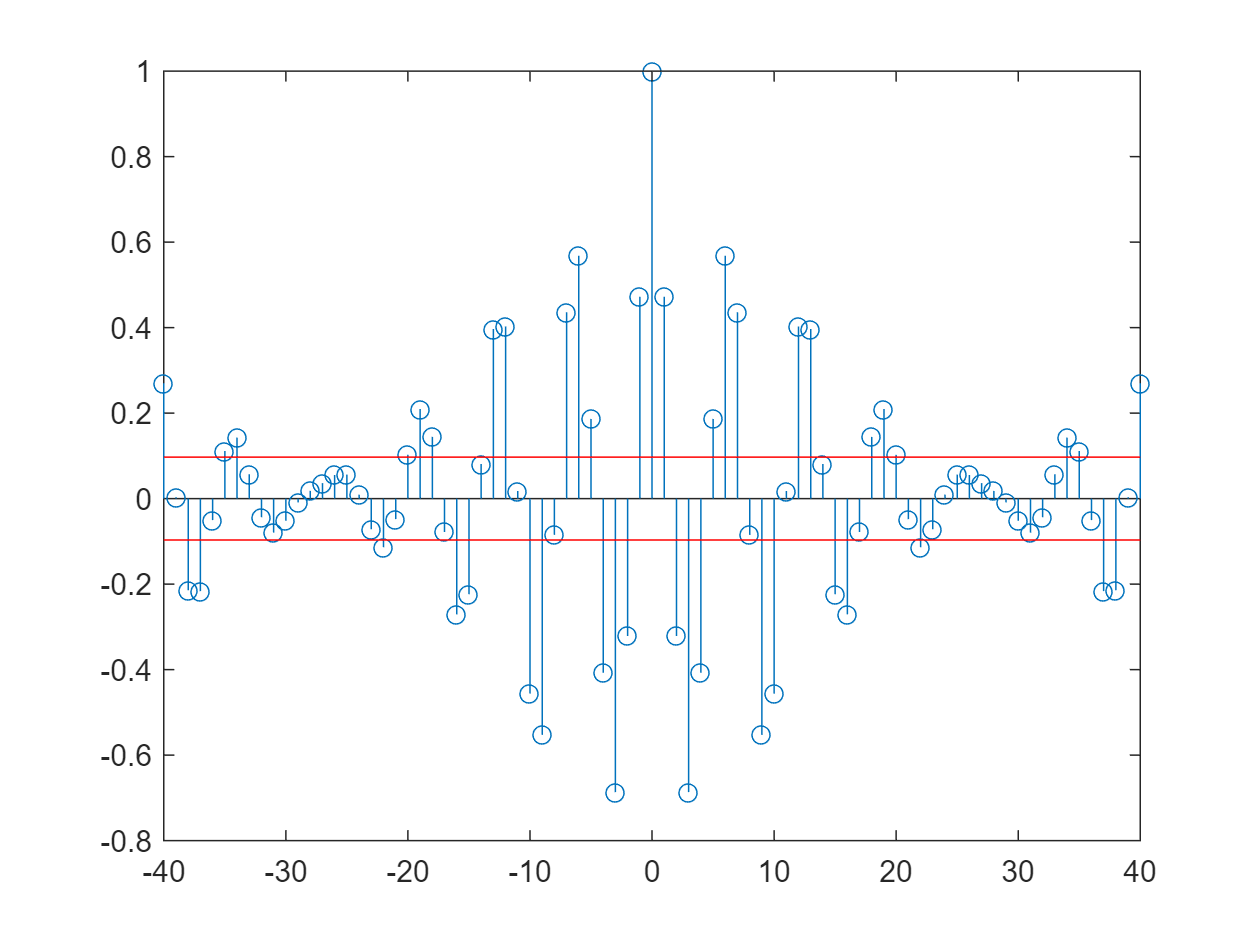

N = length(uvalid);
x = xcorr(err,err);
x = x/x(N);
stem(-40:1:40,x(N-40:N+40));
line([-40 40],[2.17/sqrt(N) 2.17/sqrt(N)],'color','r');
line([-40 40],[-2.17/sqrt(N) -2.17/sqrt(N)],'color','r');

The data in this case, again did not have a pure gaussian white noise, and was a lot worse than the data obtained by prbs.

## 3) Identification of a Discrete Time Model (ELS)

### **3.1) Using combinations of na, nb, &nc values**

A loop was run with na, nb, and nc values varying from 0 to 10. The minimum value of J was identified (5.32e-17), and the values of na, nb, & nc that falls within 30% of the minimum J as well as the 1% error of the dcgain were printed out. 

Jb = ones(10,10);
AICb = ones(10,10);
minJ = 1;
for nx=1:10
    for ny=1:10
        for nz=1:10
            na = nx;
            nb = ny;
            nc = nz;
            nk = 3;
            [A,B,C] = ELS(uident,yident,na,nb,nc,nk);
            [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C);
            Jb(nx,ny,nz) = J;
            AICb(nx,ny,nz) = AIC;

            if J < minJ
                minJ = J;
    
            end

        end 
    end
end
minJ

minJ = 5.3232e-17

for nx=1:10
    for ny=1:10
        for nz=1:10
            if Jb(nx,ny,nz) < minJ*1.3
           
                [A,B,C] = ELS(uident,yident,nx,ny,nz,3);
                sysid = tf(B,A,Ts,'variable','z^-1');
                if dcgain(sysid)>0.99
                    nx; ny; nz;
                end
            end

        end 
    end
end

### 3.2) Validation was performed to identify good values

To find the best na, nb, and nc values from the ones printed above, and keeping in mind that a higher value of na & nb would lead to a better model but also, a higher order model is difficult to control. Thus, through validation a balance was struck between precision and order of model. 

By trail and error, the printed values that deemed to be acceptable are na = 7, nb = 7, and nc = 7. 

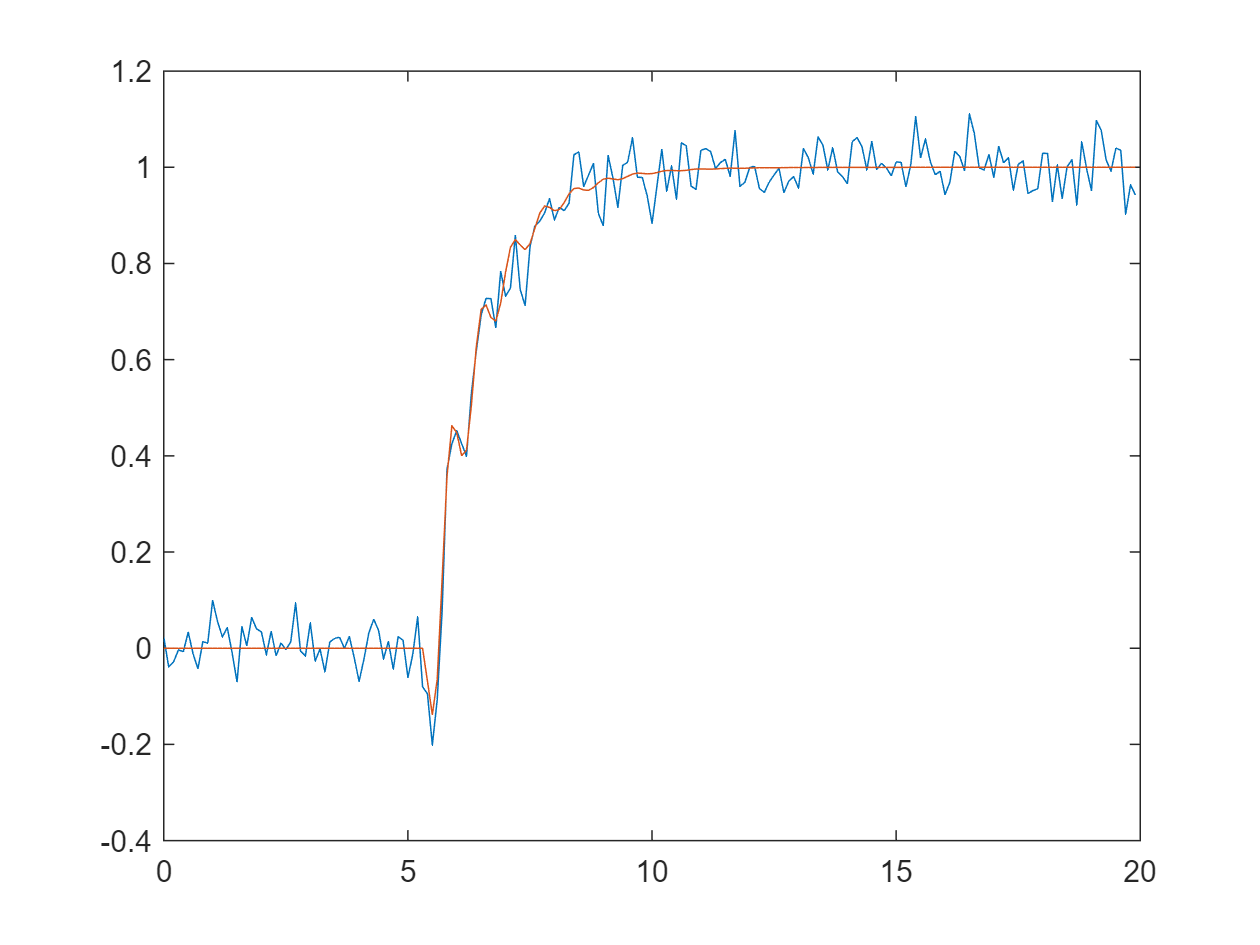

na = 7; %nb of poles
nb = 7; %nb of zeros 
nc = 7;
nk = 3; % fixed cnst value

[A,B,C] = ELS(uident,yident,na,nb,nc,nk);
sysid = tf(B,A,Ts,'variable','z^-1');
ysim = lsim(sysid,ustep,Tstep);
plot(Tstep,ystep,Tstep,ysim);

### 3.3) Analysis of Residuals 

N = length(uvalid);
x = xcorr(err,err);
x = x/x(N);
stem(-40:1:40,x(N-40:N+40));
line([-40 40],[2.17/sqrt(N) 2.17/sqrt(N)],'color','r');
line([-40 40],[-2.17/sqrt(N) -2.17/sqrt(N)],'color','r');

## Conclusion

In conclusion, the proposed transfer function of the system has 4 poles, 4 zeros, and a delay of 3. This is based on the ELS method applied to the prbs data. The residuals in the prbs were within the threshold to a greater extent than the estimation based of 211 data. Additionally, the transfer function obtained was of a lower order than that obtained by RLS, which is good from a controller design point of view.

Thus, the transfer function can be given by

[A,B,C] = ELS(uident,yident,na,nb,nc,nk);
sysid = tf(B,A,Ts,'variable','z^-1');
sysid

sysid =
 
                                                                                                
  -0.06854 z^-4 - 0.06006 z^-5 + 0.08224 z^-6 + 0.1894 z^-7 + 0.1782 z^-8 + 0.09289 z^          
                                                                                                
                                                                              -9 + 0.02154 z^-10
                                                                                                
  ----------------------------------------------------------------------------------------------
                                                                                                
  1 - 0.1408 z^-1 + 0.01502 z^-2 + 0.09442 z^-3 + 0.02426 z^-4 - 0.1358 z^-5 - 0.24 z^          
                                                                                                
                                                                                -6 - 0.1813 z^-7
                    

## *****************************************************************************************

### Identification of a continuous time model (optional)

The model is (here $\textrm{na}=2$ and $\textrm{nb}=1$ but generalization is straightforward) :

 
$$\frac{Y\left(s\right)}{U\left(s\right)}=\frac{b_1 s+b_0 }{s^2 +a_1 s+a_0 }$$


Can be re-written as a regression problem:


$$\frac{d^2 y\left(t\right)\;}{{\textrm{dt}}^2 }=\left\lbrack \begin{array}{cccc}
-\frac{\textrm{dy}\left(t\right)}{\textrm{dt}} & -y\left(t\right) & \frac{\textrm{du}\left(t\right)}{\textrm{dt}} & u\left(t\right)
\end{array}\right\rbrack \times {\left\lbrack \begin{array}{cccc}
a_1  & a_0  & b_1  & b_0 
\end{array}\right\rbrack }^T =\left\lbrack \begin{array}{cccc}
-y^{\left(1\right)} \left(t\right) & -y^{\left(0\right)} \left(t\right) & u^{\left(1\right)} \left(t\right) & u^0 \left(t\right)
\end{array}\right\rbrack \times \theta^T \;$$


Finding the coeficient from a LS solution requires the computation of derivatives of $u\left(t\right)$ and $y\left(t\right)$, very bad for high order derivation especially if the data are noisy.

The well known solution is the "state variable filter" where the $i-\textrm{th}$ derivative is approximated by a filter $F^{\left(i\right)} \left(s\right)$:


$$F^{\left(i\right)} \left(s\right)=\frac{s^i }{{\left(1+\lambda \;\right)}^{\textrm{na}+1} }$$


With $\lambda \;$ a filter coeffcient adapted to the expected bandwidth of the identified system.

The regression problem is now composed with filtered derivatives:


$$y_f^{\left(2\right)} \left(t\right)=\left\lbrack \begin{array}{cccc}
-y_f^{\left(1\right)} \left(t\right) & -y_f^{\left(0\right)} \left(t\right) & u_f^{\left(1\right)} \left(t\right) & u_f^0 \left(t\right)
\end{array}\right\rbrack \times \theta^T \;$$


Fls = svf(uident,yident,Ts,3,1,[],5)

Fls =
 
          -6.805 s + 22.71
  --------------------------------
  s^3 + 4.41 s^2 + 29.01 s + 22.46
 
Continuous-time transfer function.



It is well known that the regression problem $y=\phi \;\times \theta {\;}^T +v$ is efficiently solved by the Least Square algorithm if $v$ is white noise and zero mean. Unfortunately the svf algorithm generates a "filtered regression" such as:

 
$$y_f ={\phi \;}_f \times \theta {\;}^T +v_f$$


Where $\phi_f$and $v_f$ are now correlated and $v_f$ is not white noise anymore. The estimate will be always biased.

The solution is the Instrumental Variable solution. The instrument is generated with a model obtained with a Least Square algorithm:

Fiv = ivsvf(uident,yident,Ts,3,1,Fls,[],5)

Fiv =
 
           -9.116 s + 30.2
  ---------------------------------
  s^3 + 7.275 s^2 + 37.65 s + 30.24
 
Continuous-time transfer function.



## Validation of the continuous time model

Basic validation: compare step responses

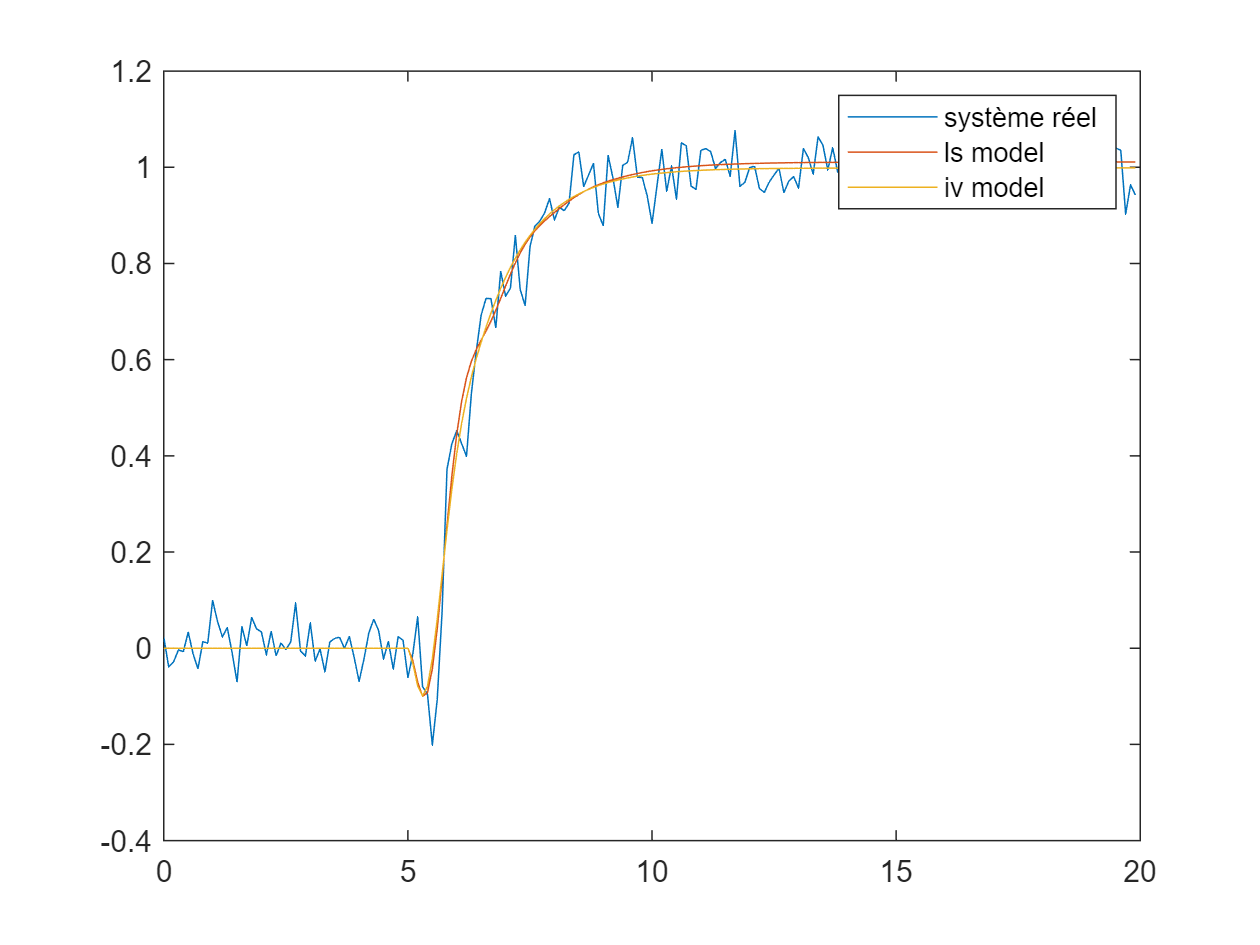

plot(Tstep,ystep,Tstep,lsim(Fls,ustep,Tstep),Tstep,lsim(Fiv,ustep,Tstep))
legend('système réel','ls model','iv model')

AIC criteria; J criteria

(TBD)

# Algorithms

### Recursive Least Square

function [A,B] = RLS(uid,yid,na,nb,nk)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
theta = zeros(na+nb,1);
D = 10^6*eye(na+nb);
%Recursive algorithm
for t = max([na nb+nk]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1)];
    yhatprior = theta'*phi;
    eps0 = yid(t+1)-yhatprior;
    epsposterior = eps0/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior;
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end
A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
end

### Recursive Extended Least Square

function [A,B,C] = ELS(uid,yid,na,nb,nc,nk)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
theta = zeros(na+nb+nc,1);
D = 10^6*eye(na+nb+nc);
epsposterior = zeros(length(yid),1);
eps0 = zeros(length(yid),1);
%Recursive algorithm
for t = max([na nb+nk nc]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1);epsposterior(t:-1:t-nc+1)];
    yhatprior = theta'*phi;
    eps0(t+1) = yid(t+1)-yhatprior;
    epsposterior(t+1) = eps0(t+1)/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior(t+1);
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end

A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
C = theta(na+nb+1:end)';
end

### Prediction Error and AIC criteria

function [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C)
N = length(uvalid);
if nargin == 4
    C = [];
end
uvalid = reshape(uvalid,[],1);
yvalid = reshape(yvalid,[],1);
A = A(2:end);
B = B(2:end);
na=length(A);
nb=length(B);
nc=length(C);
theta = [A';B';C'];
err = zeros(N,1);
%Recursive algorithm
for t = max([na nb nc]):(length(yvalid)-1)
    phi = [-yvalid(t:-1:t-na+1);uvalid(t:-1:t-nb+1);err(t:-1:t-nc+1)];
    err(t+1) = yvalid(t+1)-theta'*phi;
end
J = 1/N*(err'*err);
AIC = log(J)+2*(na+nb+nc)/N;
end

## Identification of continuous time model

function F = svf(uid,yid,Ts,na,nb,nk,lambda)
% Identification of a continuous-time model from sampled data
% uid: input data
% yid: output data
% Ts: sampling time (s)
% na: order of the denominator
% nb: order of the denominator
% nk: delay in samples (if known), default 0
% lambda: time constant of the svf, default lambda = 5*Ts
% Algorithm based on "Identification of Continuous-time Models from Sampled Data
% Garnier, Wang. Springer
narginchk(5,7);
switch nargin
    case 6
        lambda = Ts*5;
    case 5
        lambda = Ts*5;
        nk = 0;
end
if isempty(nk), nk = 0; end
if isempty(lambda), lambda = Ts*5;end
if nb>na error('nb must be less or equal to na (proper transfer function)');end

N = length(uid);
uid = reshape(uid,[N 1]);
yid = reshape(yid,[N 1]);

T = 0:Ts:(N-1)*Ts;
s = tf('s');
f = 1/(s+lambda)^(na+1);
PHIu = lsim(f,uid,T);
for k = 1:nb
    f = s*f;
    PHIu = [lsim(f,uid,T) PHIu];
end
s = tf('s');
f = 1/(s+lambda)^(na+1);
PHIy = -lsim(f,yid,T);
for k = 1:na-1
    f = s*f;
    PHIy = [-lsim(f,yid,T) PHIy];
end
PHI = [PHIy PHIu];
f = s*f;
Y = lsim(f,yid,T);
theta = pinv(PHI)*Y;
A = [1 theta(1:na)'];
B = theta(na+1:end)';
F = tf(B,A);
end

function F = ivsvf(uid,yid,Ts,na,nb,F0,nk,lambda)
% Identification of a continuous-time model from sampled data
% uid: input data
% yid: output data
% Ts: sampling time (s)
% na: order of the denominator
% nb: order of the denominator
% nk: delay in samples (if known), default 0
% lambda: time constant of the svf, default lambda = 5*Ts
% F0: initial guess for the model (lti model)
% Algorithm based on "Identification of Continuous-time Models from Sampled Data
% Garnier, Wang. Springer
narginchk(5,8);
switch nargin
    case 7
        lambda = Ts*5;
    case 6
        lambda = Ts*5;
        nk = 0;
end
if isempty(nk), nk = 0; end
if isempty(lambda), lambda = Ts*5;end
if nb>na error('nb must be less or equal to na (proper transfer function)');end

N = length(uid);
uid = reshape(uid,[N 1]);
yid = reshape(yid,[N 1]);



T = 0:Ts:(N-1)*Ts;
s = tf('s');
f = 1/(s+lambda)^(na+1);
PHIu = lsim(f,uid,T);
for k = 1:nb
    f = s*f;
    PHIu = [lsim(f,uid,T) PHIu];
end
s = tf('s');
f = 1/(s+lambda)^(na+1);
PHIy = -lsim(f,yid,T);
for k = 1:na-1
    f = s*f;
    PHIy = [-lsim(f,yid,T) PHIy];
end
z = lsim(F0,uid,T);
s = tf('s');
f = 1/(s+lambda)^(na+1);
PHIz = -lsim(f,z,T);
for k = 1:na-1
    f = s*f;
    PHIz = [-lsim(f,z,T) PHIz];
end

PHI = [PHIy PHIu];
Z = [PHIz PHIu];
f = s*f;
Y = lsim(f,yid,T);
theta = (Z'*PHI)\Z'*Y; % (better than (Z'*PHIu)^-1*Z'*Y)
A = [1 theta(1:na)'];
B = theta(na+1:end)';
F = tf(B,A);
end